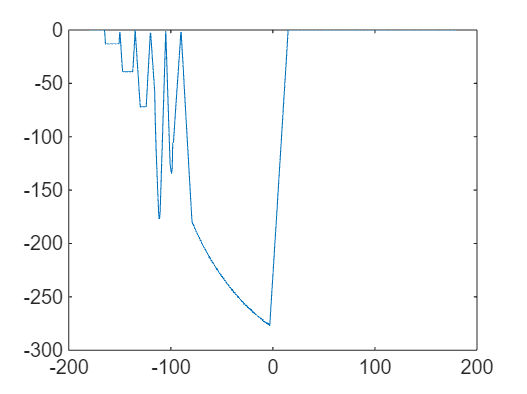

clc
clear 
rng(2024)


% 按照设定相位生成初始卫星队列
sat_num=19;
for k = 1:sat_num
    sat_index(1,k) = 0 + (k-1)*15; % initial phase index
end
sat_array=gen_satellite_array_by_index(sat_index);
A=gen_matrix_A(sat_array);
sat_group=gen_sat_group(sat_array);

h=1;
days=1;
for i=1:sat_num
    sat_array{i}=sat_array{i}.set_time_parameters(days,h);
    sat_array{i}=sat_array{i}.update();
end


% 取出一组邻近卫星索引,并累加邻近卫星的时间窗口
opt_group=sat_group(1,:);
index=1:1:sat_num;
index=index(opt_group~=0);

tau=zeros(1,length(sat_array{1}.tau));
flag=1;
for j=1:length(index)

    if j==flag
        continue
    else
        tau=tau+sat_array{j}.tau;
    end
end

% 
% sat_array{flag}=sat_array{flag}.set_orbit_parameters(-20);
% sat_array{flag}=sat_array{flag}.update();

gama=0;

x=linspace(-180,180,1000);
for i=1:length(x)
    a(i)=cal_ob_fun(x(i),tau,sat_array{flag},gama);
end
plot(x,a)




fun=@(x)cal_ob_fun(x,tau,sat_array{flag},gama);






% 遗传算法
tic
lb = -180;    
ub = 180;     
nVars = 1;   
options = optimoptions('ga', 'PopulationSize', 100, 'MaxGenerations', 1000); 
[x, fval] = ga(fun, nVars, [], [], [], [], lb, ub, [], options);

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


disp(['最优解: ', num2str(x)]);  

最优解: -7.3843


disp(['目标函数值: ', num2str(-fval)]);  

目标函数值: 274



toc

历时 15.088727 秒。





% 
% %surrogateop方法
% tic
% options = optimoptions('surrogateopt','Display','iter');
% [x,fval] = surrogateopt(fun,-180,180,options)
% toc


% % fminbnd方法
% tic
% options = optimset('Display','iter');
% [x,fval] = fminbnd(fun,-180,180,options)
% toc
















% phi=linspace(-18,720,1000);
% for i=1:length(phi)
%     a=Satellite(phi(i));
%     a=a.set_time_parameters(1,1);
%     a=a.update();
% 
%     tau(1,i)=sum(a.tau)*(a.h/a.days);
% end
% plot(phi,tau)
% a=Satellite(-20);
% sum(a.tau)*(a.h/a.days)
% 
% 360/15
























% 不采用的算法方案和参数，



% fun = @opt;  % 创建函数句柄
% x0 = 5;  % 初始点
% theta_max=3;
% A=[];
% b=[];
% Aeq=[];
% beq=[];
% lb=[-6];
% ub=[6];
% options = optimoptions('fmincon', 'Display', 'iter','Algorithm','active-set');
% [x, fval] = fmincon(fun, x0, A, b, Aeq, beq, lb, ub, [], options);




% 遗传算法
% populationSize = 50;  % 种群大小  
% maxGenerations = 100;  % 最大迭代次数  
% crossoverFraction = 0.8;  % 交叉概率  
% mutationFcn = {@mutationgaussian, 0.1};  % 高斯变异函数和标准差 
% 
% 
% 



% % 随机分布19个卫星在默认轨道
% 
% sat_num=19;
% sat_array=gen_satellite_array(sat_num);
% A=gen_matrix_A(sat_array);
% sat_group=gen_sat_group(sat_array);